# Computer Assignment #3

## Ali Hamzehpour 810100129

### part one

In this part we want to encode a message in an image and then decode it.

### 1-1

    First of all, we have to map each character to a binary number. We use lowercase letters and some additional charcters( " . , ; ! and space). we make a mapset which is basically a 32 * 2 cell and in each 1 * 2 we have a character and a binary number:

map_set = cell(2, 32);

letters = ['a':'z'];
for i = 1:numel(letters)
    binary_string = dec2bin(i-1, 5);
    map_set{1, i} = letters(i);
    map_set{2, i} = binary_string;
end

special_chars = [' ', '!', '.', ',', '"', ';'];
for i = 1:numel(special_chars)
    binary_string = dec2bin(i+25, 5);
    map_set{1, i+26} = special_chars(i);
    map_set{2, i+26} = binary_string;
end

### 1-2

    In this section, we implement a function that gets a gray-scale image, a message and a map set(the one we made in the previous section) then we encode the mssage in the given image.

The way we encode the message is we convert the whole message into a binary string then we assign the least significant bit of pixels' values to that binary string bits:

function encoded_img = coding(msg, gray_img, map_set)    
    msg_code = '';
    for i = 1 : length(msg)
        char_code = map_set{2, strcmp(map_set(1, :), msg(i))};
        msg_code = [msg_code, char_code];
    end 
    msg_code = [msg_code];

    [height, width, ~] = size(gray_img);
    
    if length(msg_code) > height * width
        error("size of msg binary code is bigger than pixels of the image.");
    end
    
    encoded_img = gray_img;

    for i = 1 : length(msg_code)
        row = floor((i-1) / width) + 1;
        col = mod((i-1), width) + 1;
        
        pixel = encoded_img(row, col);
        parity = mod(pixel , 2);
        desired_parity = msg_code(i) - '0';
        if parity ~= desired_parity
            encoded_img(row, col) = encoded_img(row, col) + desired_parity - parity;
        end

    end
end

### 1-3

    Now we load an image and encode a message in it:

WIDTH_RESIZE = 800;
HEIGHT_RESIZE = 1000;
IMAGE_PATH = "Nunez.jpg";

img = imread(IMAGE_PATH);
img = imresize(img, [WIDTH_RESIZE HEIGHT_RESIZE]);
gray = rgb2gray(img);
msg  = 'nunez nunez nunez;';

encoded_img = coding(msg, gray, map_set);

figure
subplot(1,2,1)
imshow(gray)
title('Original Image')

subplot(1,2,2)
imshow(encoded_img)
title('Encoded Image')

 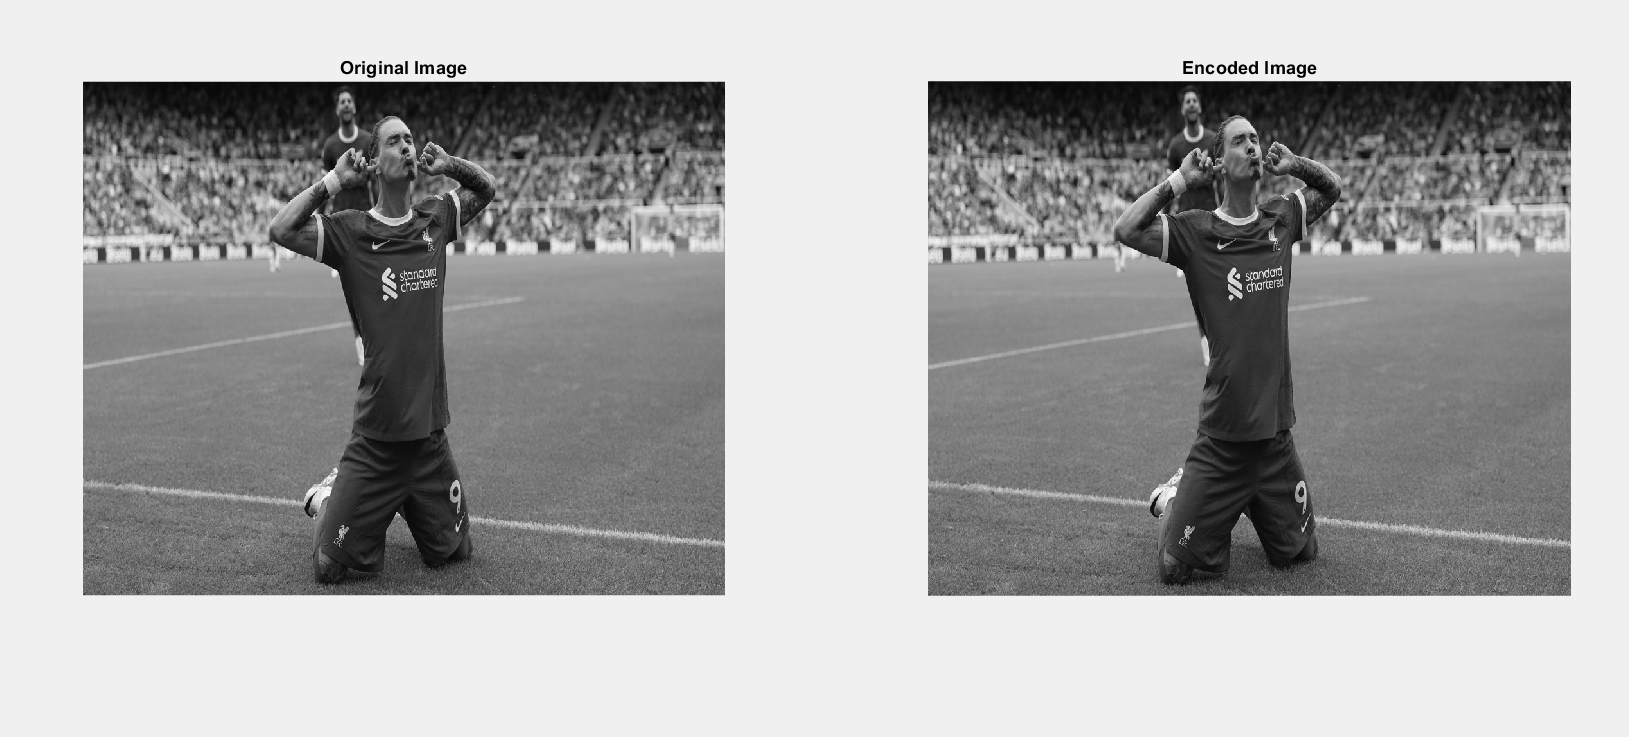

    As you can see we can't distinguish these two images from each other because we only changed the least significant bits of pixels' values and it doesn't change the pixels' values that much(the difference will be at most 1).

### 1-4

    In this part we implement a function that gets an encoded image and a map set then decode the hidden message inside the image. The way it decodes is by putting the least significant bits of the pixels together then convert that binary string to the message with the map set. We also know that ; is always the last character so we can end our process when we find thsi character:

function decoded_msg = decoding(encoded_img, map_set)
    binary_code = '';
    decoded_msg = '';
    [height, width, ~] = size(encoded_img);
    num_of_pixels = width * height;
    
    for i = 1 : num_of_pixels
        row = floor((i - 1) / width) + 1;
        col = mod((i - 1), width) + 1;
        pixel = encoded_img(row, col);
        parity = mod(pixel , 2);
        binary_code = [binary_code, num2str(parity)];
        if length(binary_code) == length(map_set{2, 1})
            decoded_msg = [decoded_msg, map_set{1, strcmp(map_set(2, :), binary_code)}];
            binary_code = '';
            if decoded_msg(end) == ';'
                break;
            end
        end
    end
end

Now if we give our encoded image to this function, we get the same message we had before:

decoded_msg = decoding(encoded_img, map_set);

fprintf("the hidden message is %s\n", decoded_msg);

### 1-5

    ***if the image contains some noise, can we decode the image?***

        Because we set the message bits in the least signifcant bits of the image we can lose them if our image gets some noise. We can encode the message more than once(repeat our message) in the image so even if the image is noisy, we may be able to understand what it's saying.

### 1-6

    ***Is there a way to undestand if an image has a hidden message?*** 

    We can use Natural Language Processing data to determine if the last bits' string has characteristics of a real message. For example in English the most common letter is E and it appears 11% of the time. Now if we see that the most common combination of 8 bit in our binary string appears near 11%, This image has more chance of having a hidden message. This method works when the message is long enough.

### part Two

### 2-1

    In this section, we implement a function that generate a single digit's sound, Then we write another function that gets a string which is a phone number and return the sound it makes. The way we generate the sound is by generating a signal with high frequency and another with low frequency then add this two signals together. We have these high and low frequencies. For a sequence of numbers we add a rest time which when signal is silent between two numbers' sounds.

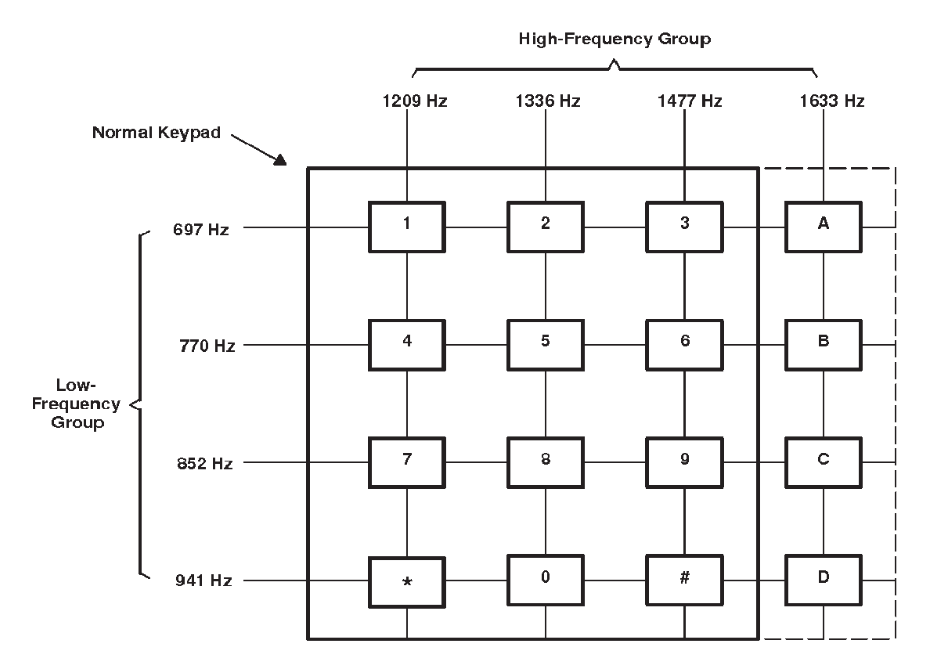

function number_sound = make_character_sound(key)
    fr = [697 770 852 941];
    fc = [1209 1336 1477];
    keypad = '1':'9';
    keypad = [keypad, '*', '0', '#'];
    fs = 8000;
    Ts = 1 / fs;
    Ton = 0.1;
    t = 0:Ts:Ton;
    keypad_index = find(keypad == key);
    row = floor((keypad_index - 1) / length(fc)) + 1;
    col = mod(keypad_index - 1, length(fc)) + 1;    
    y1 = sin(2 * pi * fr(row) * t);
    y2 = sin(2 * pi * fc(col) * t);
    number_sound = (y1 + y2) / 2;
end

function output = make_phone_number_sound(number)
    fs = 8000;
    toff = 0.1;
    output = [];
    rest_samples = round(toff * fs) + 1;
    rest_time = zeros(1, rest_samples);
    for i = 1 : length(number)
        y = make_character_sound(number(i));
        segment = [y, rest_time];
        output = [output, segment];
        %sound(y, fs);
        %pause(toff);
    end
   % sound(output, fs);

end


Now in order to use it we simply use *make_phone_number_sound *function.

number = '43218765';
fs = 8000;
y = make_phone_number_sound(number);
sound(y, fs);

### 2-2

    In this section, we get a sound and we have to determine the phone number. We split the signal into segments and then use correlation to find the the signal between digits' signal that is the closest to that segment.

function phone_number = decode_sound(y, Fs)
    segment_duration = 0.1;
    pause_duration = 0.1;
    
    segment_samples = round(segment_duration * Fs);
    pause_samples = round(pause_duration * Fs);
    
    total_segments = floor(length(y) / (segment_samples + pause_samples));
    
    segmented_audio = cell(total_segments, 1);
    
    for i = 1:total_segments
        start_index = (i - 1) * (segment_samples + pause_samples) + 1;
        end_index = start_index + segment_samples - 1;
        segmented_audio{i} = y(start_index:end_index);
    end
    
    keypad = '1':'9';
    keypad = [keypad, '*', '0', '#'];
    phone_number = '';
    
    for i = 1:length(segmented_audio)
        segment = segmented_audio{i};
        corrs = [];
        for j = 1 : length(keypad)
            number_signal = make_character_sound(keypad(j));
            corr_out = xcorr(segment, number_signal);
            corrs = [corrs, max(abs(corr_out))];
        end      
        [max_value, max_index] = max(corrs);
        phone_number = [phone_number, keypad(max_index)];
    end
end

If we give a.wav file we get 810198 as output and when I give my own number's sound it also works correctly.

number = '09308404211';
y = make_phone_number_sound(number);
sound(y, 8000);
[y2, Fs] = audioread('a.wav');

std_number = decode_sound(y2, Fs);
phone_number = decode_sound(y, Fs);

### part Three

    In this part we have to detect an IC on a board. We use normalized correlation to detect the IC. We also flip the IC image to detect flipped ICs on the board:

IC image:

board image:

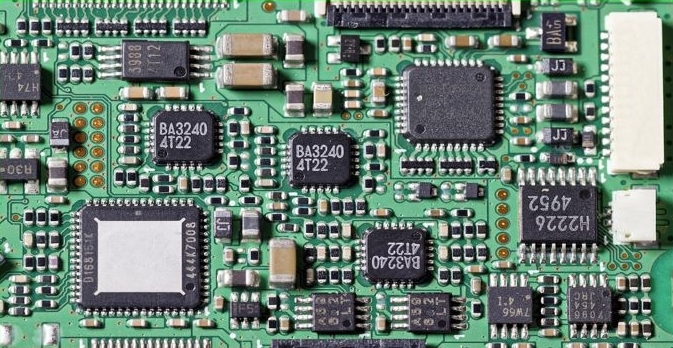

We implement the correlation ourselves by normalizing the ic image and board image and then using this formula: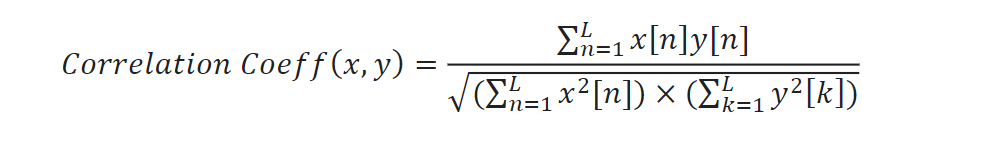

function correlation = normxcorr2_custom(template, search)
    template = normalize_image(template);
    search = normalize_image(search);

    [template_height, template_width] = size(template);
    [search_height, search_width] = size(search);

    correlation = zeros(search_height - template_height + 1, search_width - template_width + 1);

    for i = 1:size(correlation, 1)
        for j = 1:size(correlation, 2)
            region = search(i:i+template_height-1, j:j+template_width-1);

            numerator = sum(sum(template .* region));
            denominator = sqrt(sum(sum(template.^2)) * sum(sum(region.^2)));
            correlation(i, j) = numerator / denominator;
        end
    end
end

function normalized_image = normalize_image(image)
    image = im2double(image);
    mean_value = mean(image(:));
    std_value = std(image(:));

    normalized_image = (image - mean_value) / std_value;
end

Now we can implement ICrecognition function by using our correlation function:

function ICrecognition(ic, board)
    board_gray = rgb2gray(board);
    ic_gray = rgb2gray(ic);
    
    correlation = normxcorr2_custom(ic_gray, board_gray);
    
    ic_gray_flipped = flipud(fliplr(ic_gray));
    
    correlation_flipped = normxcorr2_custom(ic_gray_flipped, board_gray);
    
    threshold = 0.7;
    
    [ypeak, xpeak] = find(correlation > threshold * max(correlation(:)) | correlation_flipped > threshold * max(correlation_flipped(:)));
    
    figure;
    imshow(board);
    hold on;
    for i = 1:length(xpeak)
        rectangle('Position', [xpeak(i), ypeak(i), size(ic_gray,2), size(ic_gray,1)], 'EdgeColor', 'r', 'LineWidth', 2);
    end
    title('IC Locations on the Board');
    hold off;
    
end

Then when we use this function we get the desired output:

board = imread('PCB.jpg');
ic = imread('IC.png');

ICrecognition(ic, board);